### **Método da Bisseção**


$$x^{k+1} = \frac{a^{k}+b^{k}}{2}$$
 

Vamos encontrar o zero da função $f(x) = e^{x}-3x^2$ no intervalo de $[0.5,1]$ utilizando o método da bisseção com precisão igual ou menor que $10^{-2}$.

Graficamente, 

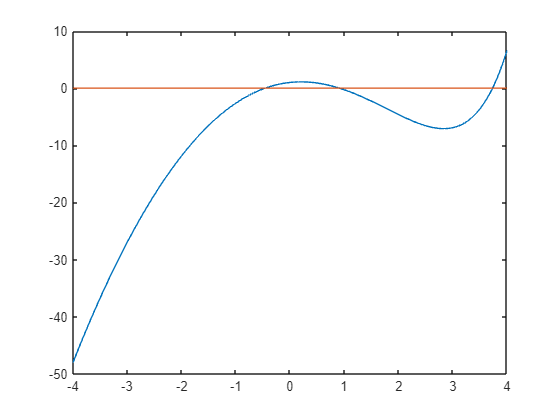

x= -4:0.01:4;
y = exp(x)-3*x.^2;
plot(x,y)
y1 = 0*x;
hold on 
plot(x,y1)

**Implementação do método da Bisseção**

format long
%Entradas
a = 0.5;
b = 1;
tol = 0.01;
%Avaliando a função em x=a e x=b
fa = exp(a)-3*a^2;
fb = exp(b)-3*b^2;
%Inicializando o chute
x0 = (a+b)/2;

fx0 = exp(x0)+3*x0^2;

%Critério de parada
er = abs(b-a)/2;
%Looping
k = 0;
while (er > tol)
    k = k + 1;
    if fa*fx0 < 0
        b = x0;
        fb = exp(b)-3*b^2;
    else
        a = x0;
        fa = exp(a)-3*a^2;
    end
    x0 = (a+b)/2; %Atualização do chute
    fx0 = exp(x0)-3*x0^2;
    er = abs(b-a)/2;
end
fprintf('Uma aproximação para o erro da função é x = %f',x0);

Uma aproximação para o erro da função é x = 0.914062

fprintf('A quantidade de iterações foi k = %d',k);

A quantidade de iterações foi k = 5

Comparando com a conta para o número de iterações temos:


$$iteracoes = \frac{log(b-a) - log(tol)}{log(2)}$$


iteracoes = (log10(1-0.5)-log10(10^(-2)))/log10(2) 

iteracoes =    5.643856189774724


**Como implementar e obter o resultado de todas as iterações?**

format long
%Entradas
a = 0.5;
b = 1;
tol = 0.01;
%Avaliando a função em x=a e x=b
fa = fun(a);
fb = fun(b);
%Inicializando o chute
x0 = (a+b)/2;
fx0 = fun(x0);
xk(1,:) = x0;
fx(1,:) = fx0;
%Critério de parada
er = abs(b-a)/2;
erk(1,:) = er;
%Looping
k = 0;
while (er > tol)
    k = k + 1;
    if fa*fx0 < 0
        b = x0;
        fb = fun(b);
    else
        a = x0;
        fa = fun(a);
    end
    x0 = (a+b)/2; %Atualização do chute
    fx0 = fun(x0);
    er = abs(b-a)/2;

    % armazenando os valores obtidos nas iterações
    xk(k+1,:) = x0;
    fx(k+1,:) = fx0;
    erk(k+1,:) = er;
end
[xk fx erk]

ans =    0.750000000000000   0.429500016612675   0.250000000000000
   0.875000000000000   0.102000293967098   0.125000000000000
   0.937500000000000  -0.083129291937073   0.062500000000000
   0.906250000000000   0.011156582463025   0.031250000000000
   0.921875000000000  -0.035560823837477   0.015625000000000
   0.914062500000000  -0.012095139739635   0.007812500000000


function y = fun(x)
    y = exp(x)-3*x^2;
end